clear
rosshutdown()

Shutting down global node /matlab_global_node_47688 with NodeURI http://192.168.1.33:54041/


rosinit("http://192.168.1.42:11311")

Initializing global node /matlab_global_node_02085 with NodeURI http://192.168.1.33:54066/


sub = rossubscriber("/map",DataFormat="struct");
msg = receive(sub);

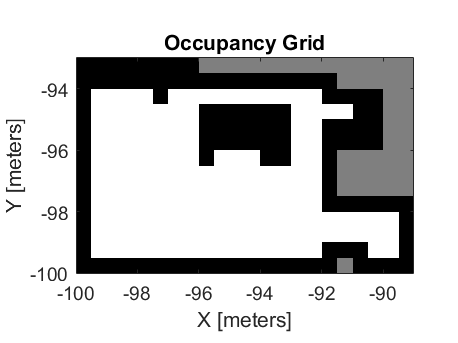


%emptyMap = rosmessage("nav_msgs/OccupancyGrid",DataFormat="struct");
occupancyMapObj = rosReadOccupancyGrid(msg);
occupancyMapObj = occupancyMap(occupancyMapObj,11);
occupancyMapObj = occupancyMap(occupancyMapObj,2);
mat = occupancyMatrix(occupancyMapObj);
show(occupancyMapObj);




%map = rosReadOccupancyGrid(msg);
%show(map)
%pub = rospublisher("/scan","sensor_msgs/LaserScan","DataFormat","struct")